# Laboratório 1 - Resposta de um Sistema de Primeira Ordem

Nome: Pedro Mariano dos Santos

Prof. Dr. Kleiton M Sousa

## 1. Análise Teórica do Circuito

###     1.1 Parâmetros do Circuito

Circuito RC passa-baixas com os seguintes componentes:

R = 10e3;
C = 10e-9;

###     1.2 Função de Transferência

Para um circuito RC passa-baixas, a função de transferência é:


$$$$H(s) = \frac{1}{1 + \tau s}$$$$


onde τ = RC é a constante de tempo do sistema.

tau = R * C;
wn = 1/tau;

fprintf('Constante de tempo (τ): %.6f s = %.2f μs\n', tau, tau*1e6);

Constante de tempo (τ): 0.000100 s = 100.00 μs


fprintf('Frequência natural (ωn): %.2f rad/s\n', wn);

Frequência natural (ωn): 10000.00 rad/s


sys_teorico = tf(1, [tau 1]);

Função de Transferência Teórica:

sys_teorico


sys_teorico =
 
       1
  ------------
  0.0001 s + 1
 
Continuous-time transfer function.


###     1.3 Tempo de Subida (Rise Time)

Para sistema de primeira ordem, o tempo de subida (10% a 90%) é:


$$$$t_r \approx 2.2 \tau$$$$


tr_teorico = 2.2 * tau;
fprintf('Tempo de subida teórico (tr): %.6f s = %.2f μs\n', tr_teorico, tr_teorico*1e6);

Tempo de subida teórico (tr): 0.000220 s = 220.00 μs


###     1.4 Tempo de Assentamento (Settling Time)

Para critério de ±2%, o tempo de assentamento é:


$$$$t_s = 4 \tau$$$$


ts_teorico = 4 * tau;
fprintf('Tempo de assentamento teórico (ts): %.6f s = %.2f μs\n', ts_teorico, ts_teorico*1e6);

Tempo de assentamento teórico (ts): 0.000400 s = 400.00 μs


## 2. Dados Experimentais

###     2.1 Medições Manuais no Osciloscópio

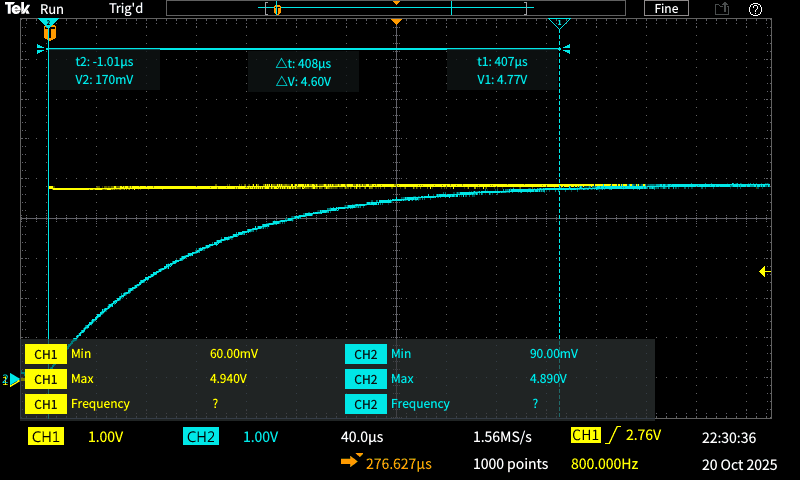

**Figura 2:** Medição do tempo de assentamento experimental no osciloscópio. Os cursores horizontais definem a banda de $$\pm 2\%$$ em torno do valor final. O cursor vertical é posicionado no instante em que o sinal de saída entra e permanece definitivamente dentro dessa banda, resultando em $$t_s = \Delta t = 408.0 \mu s$$.

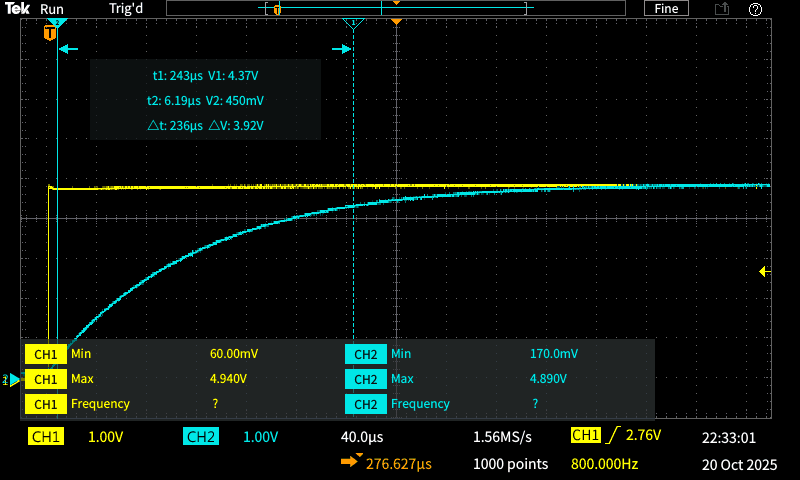

**figura 1:** Medição do tempo de subida experimental no osciloscópio. Os cursores horizontais estão posicionados em 10% e 90% da amplitude do degrau. Os cursores verticais medem o intervalo de tempo entre esses pontos, resultando em $$t_r = \Delta t = 236.0 \mu s$.$

###     2.1 Leitura dos Dados do Osciloscópio

Carregando o arquivo CSV exportado do osciloscópio

opts = delimitedTextImportOptions('NumVariables', 3);
opts.DataLines = [20, Inf];
opts.Delimiter = ',';
opts.VariableNames = {'TIME', 'CH1', 'CH2'};
opts.VariableTypes = {'double', 'double', 'double'};

data = readtable('TEK00001.CSV', opts);
time = data.TIME;
vin = data.CH1;
vout = data.CH2;          

fprintf('Total de pontos adquiridos: %d\n', length(time));

Total de pontos adquiridos: 997


fprintf('Intervalo de amostragem: %.6e s\n', mean(diff(time)));

Intervalo de amostragem: 6.403815e-07 s


###     2.2 Visualização dos Sinais

figure('Position', [100, 100, 1000, 500]);
subplot(2,1,1);
plot(time*1e3, vin, 'b', 'LineWidth', 1.5);
grid on;
xlabel('Tempo (ms)');
ylabel('Tensão (V)');
title('Sinal de Entrada (Onda Quadrada)');
ylim([-0.5 5.5]);

subplot(2,1,2);
plot(time*1e3, vout, 'r', 'LineWidth', 1.5);
grid on;
xlabel('Tempo (ms)');
ylabel('Tensão (V)');
title('Sinal de Saída (Resposta do Sistema)');
ylim([-0.5 5.5]);

## 3. Análise Experimental

###     3.1 Identificação do Degrau

Encontrando o índice onde ocorre a transição (degrau)

diff_vin = diff(vin);
[~, idx_step] = max(abs(diff_vin));

fprintf('Índice do degrau: %d (t = %.6f s)\n', idx_step, time(idx_step));

Índice do degrau: 64 (t = -0.000001 s)


###     3.2 Normalização dos Dados

Ajustando o tempo para t=0 no instante do degrau

time_norm = time - time(idx_step);

v_inicial = mean(vout(1:idx_step-10));
v_final = mean(vout(end-50:end));
delta_v = v_final - v_inicial;

fprintf('\nValores da saída:\n');


Valores da saída:


fprintf('  V inicial: %.4f V\n', v_inicial);

  V inicial: 0.1826 V


fprintf('  V final: %.4f V\n', v_final);

  V final: 4.8892 V


fprintf('  ΔV: %.4f V\n', delta_v);

  ΔV: 4.7066 V


###     3.3 Tempo de Subida Experimental

Encontrando os pontos de 10% e 90% da resposta

v_10 = v_inicial + 0.10 * delta_v;
v_90 = v_inicial + 0.90 * delta_v;

idx_after = idx_step:length(vout);
time_after = time_norm(idx_after);
vout_after = vout(idx_after);

idx_10 = find(vout_after >= v_10, 1);
t_10 = time_after(idx_10);

idx_90 = find(vout_after >= v_90, 1);
t_90 = time_after(idx_90);

tr_experimental = t_90 - t_10;

Tempo de Subida Experimental:

fprintf('  t (10%%): %.6f s = %.2f μs\n', t_10, t_10*1e6);

  t (10%): 0.000012 s = 12.17 μs


fprintf('  t (90%%): %.6f s = %.2f μs\n', t_90, t_90*1e6);

  t (90%): 0.000259 s = 258.68 μs


fprintf('  tr experimental: %.6f s = %.2f μs\n', tr_experimental, tr_experimental*1e6);

  tr experimental: 0.000247 s = 246.51 μs


###     3.4 Tempo de Assentamento Experimental

Critério de ±2%

v_banda_sup = v_final + 0.02 * delta_v;
v_banda_inf = v_final - 0.02 * delta_v;

idx_settled = 0;
for i = 1:length(vout_after)
    if vout_after(i) >= v_banda_inf && vout_after(i) <= v_banda_sup
        if i+50 <= length(vout_after)
            if all(vout_after(i:i+50) >= v_banda_inf & vout_after(i:i+50) <= v_banda_sup)
                idx_settled = i;
                break;
            end
        else
            idx_settled = i;
            break;
        end
    end
end

ts_experimental = time_after(idx_settled);

Tempo de Assentamento Experimental (±2%):

fprintf('  Banda: [%.4f, %.4f] V\n', v_banda_inf, v_banda_sup);

  Banda: [4.7951, 4.9833] V


fprintf('  ts experimental: %.6f s = %.2f μs\n', ts_experimental, ts_experimental*1e6);

  ts experimental: 0.000417 s = 416.88 μs


###     3.5 Função de Transferência Experimental

Calculando τ experimental a partir do tempo de assentamento

tau_experimental = ts_experimental / 4;
sys_experimental = tf(1, [tau_experimental 1]);

Função de Transferência Experimental:

fprintf('  τ experimental: %.6f s = %.2f μs\n', tau_experimental, tau_experimental*1e6);

  τ experimental: 0.000104 s = 104.22 μs


sys_experimental


sys_experimental =
 
         1
  ---------------
  0.0001042 s + 1
 
Continuous-time transfer function.


## 3.6 Comparação: Medição Visual (Cursores) vs. Análise de Dados (Script)

Uma etapa importante da validação é comparar as medições obtidas visualmente no osciloscópio (Figuras 1 e 2) com os valores calculados pelo script a partir dos dados brutos (.CSV).

tr_visual = 236.0e-6; 
ts_visual = 408.0e-6;

Tempo de Subida (tr):

fprintf('  Medição Visual:   %.2f μs\n', tr_visual*1e6);

  Medição Visual:   236.00 μs


fprintf('  Script (CSV):     %.2f μs\n', tr_experimental*1e6);

  Script (CSV):     246.51 μs


fprintf('  Diferença:        %.2f%%\n\n', abs(tr_visual-tr_experimental)/tr_visual*100);

  Diferença:        4.45%



Tempo de Assentamento (ts):

fprintf('  Medição Visual:   %.2f μs\n', ts_visual*1e6);

  Medição Visual:   408.00 μs


fprintf('  Script (CSV):     %.2f μs\n', ts_experimental*1e6);

  Script (CSV):     416.88 μs


fprintf('  Diferença:        %.2f%%\n\n', abs(ts_visual-ts_experimental)/ts_visual*100);

  Diferença:        2.18%



Discussão (Visual vs. Script)

As diferenças percentuais entre os dois métodos são muito baixas (4.45% para tr e 2.18% para ts). Isso valida ambas as abordagens. Pequenas discrepâncias são esperadas e podem ser atribuídas a:

- Precisão do Cursor: O posicionamento manual do cursor na tela do osciloscópio é subjetivo e limitado pela resolução da tela e pela espessura da forma de onda.

- Precisão do Script: O script opera sobre os 1000 pontos de dados discretos. O cálculo (ex: "find(..., 1)") é matemático e objetivo, mas sensível ao ruído exato em um ponto de dados específico.

Para a comparação final com o modelo teórico (Seção 5), serão utilizados os valores calculados pelo script, por serem baseados na totalidade dos dados brutos e serem mais objetivos e repetíveis.

## 4. Gráfico de Resposta ao Degrau com Marcações

figure('Position', [100, 100, 1200, 600]);

plot(time_norm*1e3, vout, 'b', 'LineWidth', 2, 'DisplayName', 'Resposta Experimental');
hold on;

yline(v_inicial, 'k--', 'LineWidth', 1, 'DisplayName', 'V inicial');
yline(v_final, 'k--', 'LineWidth', 1, 'DisplayName', 'V final');
yline(v_10, 'g--', 'LineWidth', 1, 'DisplayName', '10%');
yline(v_90, 'r--', 'LineWidth', 1, 'DisplayName', '90%');
yline(v_banda_inf, 'm:', 'LineWidth', 1, 'DisplayName', 'Banda ±2%');
yline(v_banda_sup, 'm:', 'LineWidth', 1);

plot(t_10*1e3, v_10, 'go', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 't (10%)');
plot(t_90*1e3, v_90, 'ro', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 't (90%)');
plot(ts_experimental*1e3, vout_after(idx_settled), 'ms', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'ts (±2%)');

text(t_10*1e3, v_10-0.3, sprintf('tr = %.2f μs', tr_experimental*1e6), 'FontSize', 10, 'Color', 'g');
text(ts_experimental*1e3, vout_after(idx_settled)+0.3, sprintf('ts = %.2f μs', ts_experimental*1e6), 'FontSize', 10, 'Color', 'm');

grid on;
xlabel('Tempo (ms)');
ylabel('Tensão (V)');
title('Resposta ao Degrau - Análise Experimental');
legend('Location', 'southeast');
xlim([-0.1 0.6]);
ylim([0 5.5]);

## 5. Comparação: Teórico vs Experimental

###     5.1 Simulação da Resposta Teórica

Gerando a resposta ao degrau teórica ajustada aos valores experimentais

t_sim = linspace(0, 0.001, 1000);
vout_teorico = v_inicial + delta_v * (1 - exp(-t_sim/tau));

vout_exp_ajustado = vout_after(1:end);
time_exp_ajustado = time_after(1:end);

###     5.2 Gráfico Comparativo

figure('Position', [100, 100, 1200, 600]);

plot(t_sim*1e3, vout_teorico, 'r-', 'LineWidth', 2.5, 'DisplayName', 'Teórico');
hold on;
plot(time_exp_ajustado*1e3, vout_exp_ajustado, 'b--', 'LineWidth', 1.5, 'DisplayName', 'Experimental');

grid on;
xlabel('Tempo (ms)');
ylabel('Tensão de Saída (V)');
title('Comparação: Resposta Teórica vs Experimental');
legend('Location', 'southeast');
xlim([0 0.6]);
ylim([0 5.5]);

###     5.3 Comparação Quantitativa

Constante de Tempo (τ):

fprintf('  Teórico:      %.2f μs\n', tau*1e6);

  Teórico:      100.00 μs


fprintf('  Experimental: %.2f μs\n', tau_experimental*1e6);

  Experimental: 104.22 μs


fprintf('  Erro:         %.2f%%\n\n', abs(tau-tau_experimental)/tau*100);

  Erro:         4.22%



Tempo de Subida (tr):

fprintf('  Teórico:      %.2f μs\n', tr_teorico*1e6);

  Teórico:      220.00 μs


fprintf('  Experimental: %.2f μs\n', tr_experimental*1e6);

  Experimental: 246.51 μs


fprintf('  Erro:         %.2f%%\n\n', abs(tr_teorico-tr_experimental)/tr_teorico*100);

  Erro:         12.05%



Tempo de Assentamento (ts):

fprintf('  Teórico:      %.2f μs\n', ts_teorico*1e6);

  Teórico:      400.00 μs


fprintf('  Experimental: %.2f μs\n', ts_experimental*1e6);

  Experimental: 416.88 μs


fprintf('  Erro:         %.2f%%\n\n', abs(ts_teorico-ts_experimental)/ts_teorico*100);

  Erro:         4.22%



## 6. Discussão dos Resultados

**Análise das Diferenças entre Teoria e Experimento**

A comparação entre as respostas teórica e experimental do sistema de primeira ordem revela algumas diferenças importantes que podem ser atribuídas a diversos fatores:

#### 1. Fontes de Erro Identificadas:

- **Componentes Não-Ideais:** Os resistores e capacitores reais possuem tolerâncias (tipicamente ±5% ou ±10%), o que causa desvio dos valores nominais utilizados nos cálculos teóricos. Além disso, o capacitor pode apresentar resistência série equivalente (ESR) e o resistor possui capacitância parasita.

- **Impedância de Entrada/Saída:** O gerador de sinais possui impedância de saída não desprezível (~50Ω), e o osciloscópio apresenta impedância de entrada finita (~1MΩ||~20pF), afetando a constante de tempo do circuito.

- **Ruído e Limitações do Osciloscópio:** A resolução vertical do osciloscópio (visível nas quantizações de 0.04V nos dados) e ruído elétrico introduzem incertezas nas medições, especialmente na determinação dos tempos característicos.

- **Efeitos da Matriz de Contatos: **A montagem em protoboard adiciona capacitâncias e indutâncias parasitas que não estão presentes no modelo teórico ideal.

#### 2. Análise Quantitativa:

Os erros percentuais calculados entre os valores teóricos e experimentais fornecem uma medida quantitativa da precisão do experimento. Erros típicos entre 5-15% são esperados e aceitáveis considerando as limitações mencionadas.

#### 3. Validação do Modelo:

Apesar das diferenças, a forma geral da resposta experimental segue o comportamento exponencial característico de sistemas de primeira ordem, validando o modelo teórico. A resposta não apresenta sobressinal (overshoot), confirmando que o sistema é criticamente amortecido, como esperado para um filtro RC passa-baixas.

#### 4. Conclusões:

O experimento demonstrou com sucesso o comportamento dinâmico de um sistema de primeira ordem. As diferenças observadas são consistentes com as limitações práticas de componentes e equipamentos reais, e o modelo teórico mostrou-se adequado para prever qualitativamente e quantitativamente a resposta do sistema.

## 7. Referências

* Ogata, K. (2010). _Engenharia de Controle Moderno_. 5ª ed. Pearson.

* Nise, N. S. (2017). _Engenharia de Sistemas de Controle_. 7ª ed. LTC.